allCells = grabFromFilter('All Usable DS');
%choose which protocols to look at
priorityOrder_1 = {'Moving_Bar'; 'Moving_Grating_Direction'}; %first field name should be one of these. Priority is in given order
priorityOrder_2 = {'_ff'; 'SP10'}; %child field name should be one of these. Priority is in given order


spikeTimes = cell(0, 0);
%grab data for up cells
for i = 1:size(allCells, 1)
    struct_i = allCells{i, 2};
    analyses = fieldnames(struct_i.Analyses_Completed);
    analysisToUse_1 = findAnalysisToUse(priorityOrder_1, analyses);
    analysisToUse_2 = findAnalysisToUse(priorityOrder_2, fieldnames(struct_i.Analyses_Completed.(analysisToUse_1)));
    loc = struct_i.Analyses_Completed.(analysisToUse_1).(analysisToUse_2);
    orientations = loc.Analysis_Results.Orientation;
    
    if loc.meta.stimTime ~= 3500 || loc.meta.speed ~= 10 || sum(sort(orientations) == 0:45:315) ~= numel(orientations)
        disp(['Excluding: ' allCells{i, 1}])
        continue
    end
    
    spikeTimesByDirection = cell(8,1);
    for j = 1:numel(loc.Analysis_Results.orientationByEpoch)
        index = find(loc.Analysis_Results.orientationByEpoch(j) == 0:45:315);
        ast = [-1, loc.Analysis_Results.allSpikeTimes{j}]; 
        if isempty(spikeTimesByDirection{index, end})
            spikeTimesByDirection{index, end} = ast;
        else
            spikeTimesByDirection{index, end+1} = ast;
        end
    end
    
    spikeTimes{end+1, 1} = spikeTimesByDirection;
    
end

Excluding: SHOKR26Lc2
Excluding: SHOKR33Lc1
Excluding: SHOKR33Lc3
Excluding: SHOKR33Lc4
Excluding: SHOKR33Lc5
Excluding: SHOKR33Lc6
Excluding: SHOKR33Lc7
Excluding: SHOKR33Lc8
Excluding: SHOKR33Lc9
Excluding: SHOKR36Lc2
Excluding: SHOKR39Lc1
Excluding: SHOKR39Lc2
Excluding: SHOKR39Lc3
Excluding: SHOKR39Lc4
Excluding: SHOKR39Lc5
Excluding: SHOKR39Lc6
Excluding: SHOKR39Lc7


## compute by direction

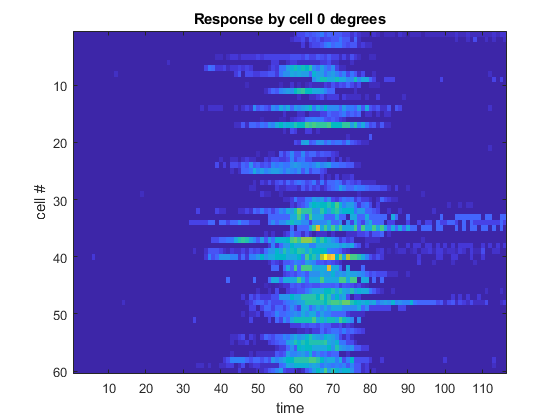

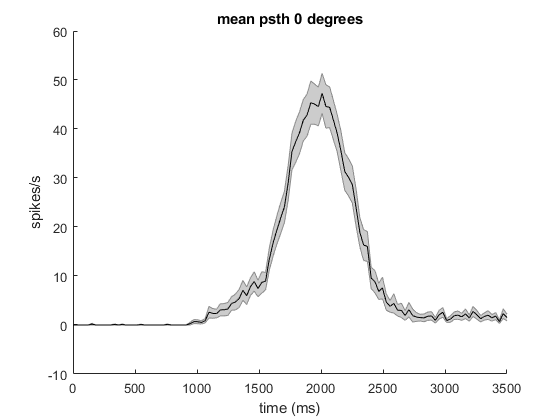

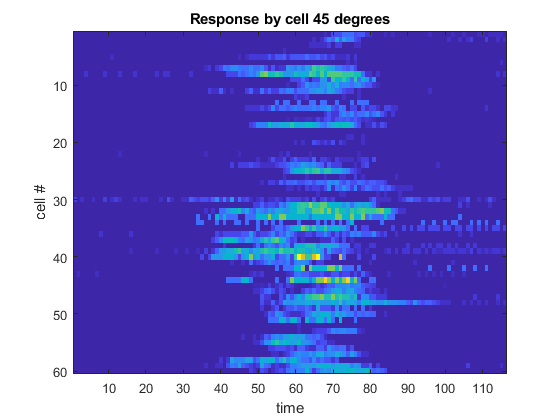

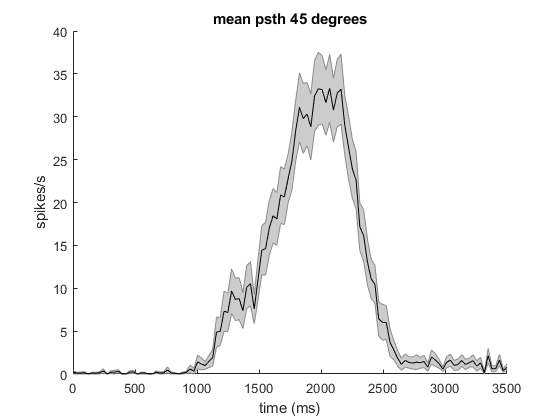

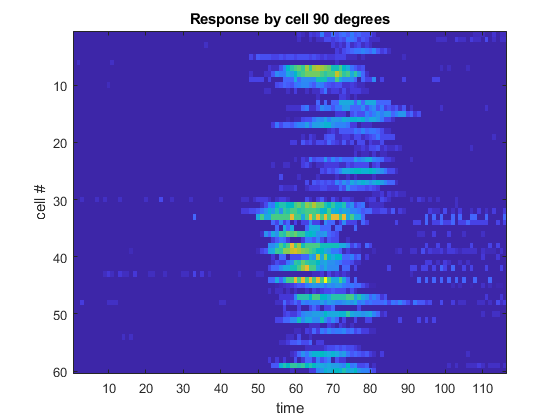

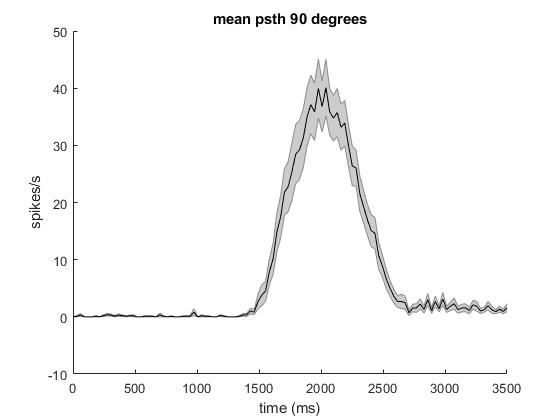

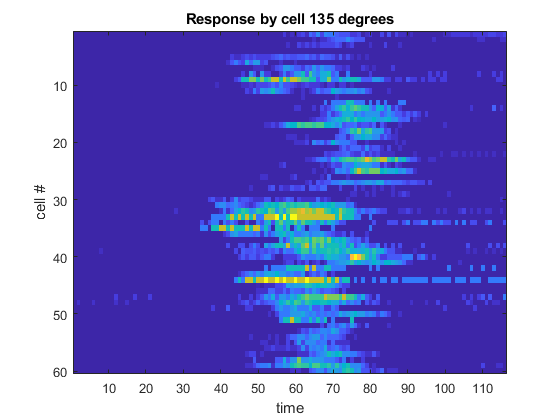

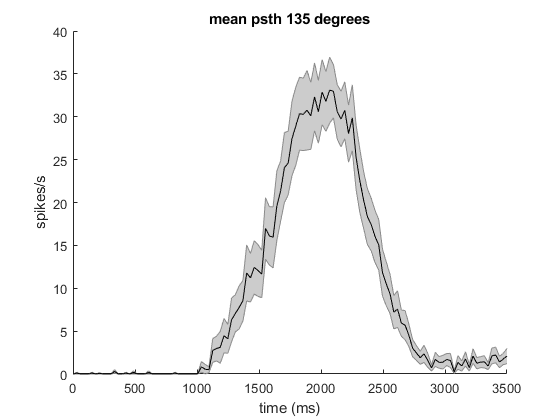

windowTime = 30; %ms
totalTime = 3500;
numBins = numel(0:windowTime:(totalTime-windowTime));
meanByCell = cell(8, numel(spikeTimes, 1));
for i = 1:8 %once for each orientation;
    %build the psth for each cell for that orientation
    results_i = [];
    for j = 1:size(spikeTimes, 1) %once for each cell
        s = spikeTimes{j};
        results_j = [];
        for k = 1:size(s, 2) %once for epoch in the given direction for this cell
            if isempty(s{i, k})
                continue
            end
            kspikes = s{i, k}-1000; %grab the spikes for this particular epoch. Subtract 1000 because only looking at stim time
            psth_k = zeros(1, numBins);
            for m = 0:numBins-1
                spikesInWindow = numel(kspikes(kspikes>m*windowTime & kspikes<(m*windowTime+windowTime)))/(windowTime/1000);
                psth_k(m+1) = spikesInWindow; %make a psth vector this epoch
            end
            results_j(k, :) = psth_k;%holds the psth for this direction, for this cell
        end

        
        if size(results_j, 1) == 1
            meanResult = results_j;
        else
            meanResult = mean(results_j);
        end
        meanByCell{i, j} = meanResult;
    end
    mat_o = zeros(size(meanByCell, 2), size(meanByCell{1}, 2));
    for o = 1:size(mat_o, 1)
        mat_o(o, :) = meanByCell{i, o};
    end
    psth = mean(mat_o);
    err = std(mat_o)./sqrt(size(mat_o, 1));
    figure
    imagesc(mat_o)
    hold on
    title(['Response by cell ' num2str((i-1)*45) ' degrees'])
    xlabel('time')
    ylabel('cell #')
    figure
    title(['mean psth ' num2str((i-1)*45) ' degrees'])
    hold on
    shadedErrorBar(linspace(1, 3500, size(psth, 2)), psth, err)
    xlabel('time (ms)')
    ylabel('spikes/s')

end

## repeat same analysis, but normalize each cell's response to its max firing rate in any direction this time

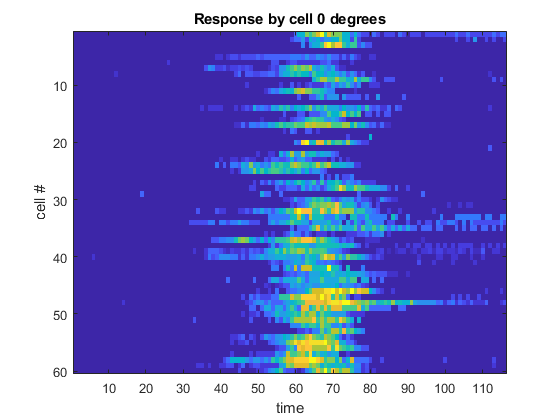

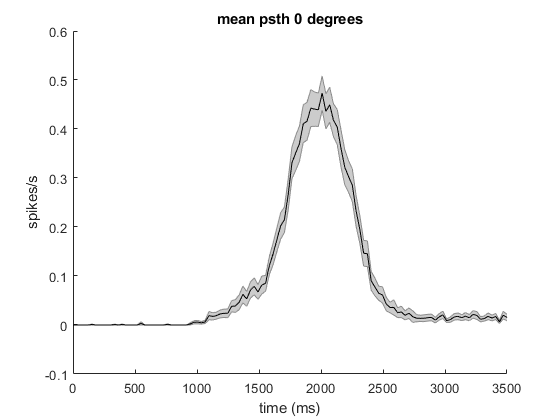

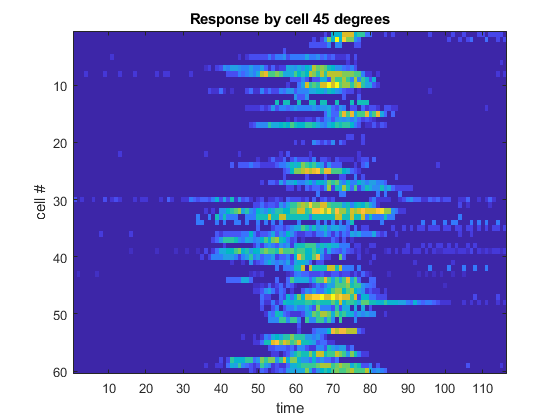

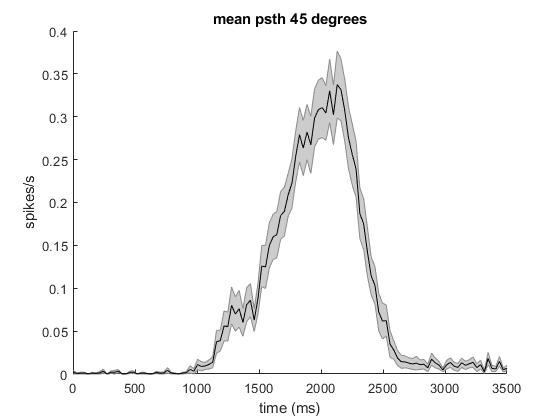

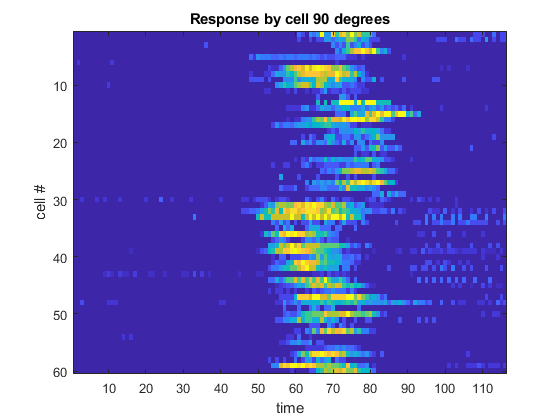

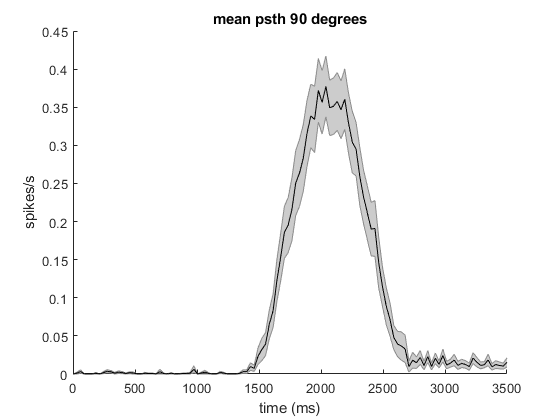

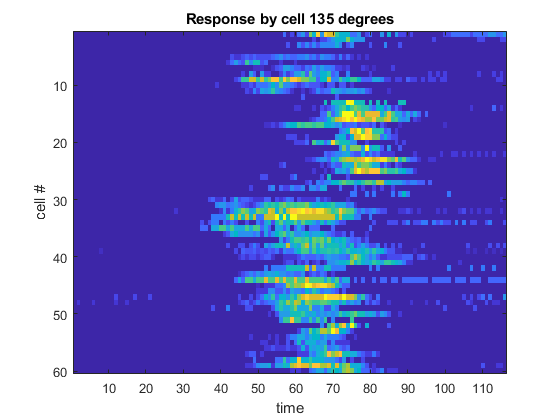

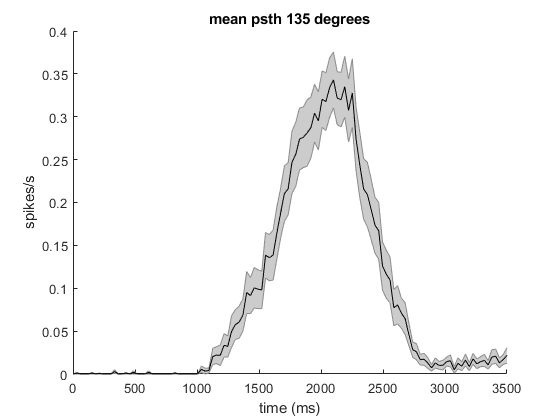

%divide each mean bin by the highest mean bin for that cell for any stimulus
normalizedResponses = meanByCell; %record the maximum firing rate in any condition for each cell
for i = 1:size(normalizedResponses, 2) %once for each cell;
    cell_i = cell2mat(normalizedResponses(:, i));
    cell_i_max = max(max(cell_i));
    cell_i_normalized = cell_i./cell_i_max; 
    normalizedResponses(:, i) = mat2cell(cell_i_normalized, repmat([1], size(cell_i, 1), 1)', [size(cell_i, 2)]);
end

psths_allDirections = [];
err_allDirections = [];
%remake histograms, with responses normalized on a per cell basis this time
for i = 1:8 %for each orientation
    
    mat_o = zeros(size(normalizedResponses, 2), size(normalizedResponses{1}, 2));
    for o = 1:size(mat_o, 1)
        mat_o(o, :) = normalizedResponses{i, o};
    end
    psth = mean(mat_o);
    err = std(mat_o)./sqrt(size(mat_o, 1));
    
    figure
    imagesc(mat_o)
    hold on
    title(['Response by cell ' num2str((i-1)*45) ' degrees'])
    xlabel('time')
    ylabel('cell #')
    hold off
    
    figure
    title(['mean psth ' num2str((i-1)*45) ' degrees'])
    hold on
    shadedErrorBar(linspace(1, 3500, size(psth, 2)), psth, err)
    xlabel('time (ms)')
    ylabel('spikes/s')
    
    psths_allDirections = [psths_allDirections;psth];
    err_allDirections = [err_allDirections; err];
end

## simulate a spatial response across cells to movement in the preferred, orthogonal, and null direction

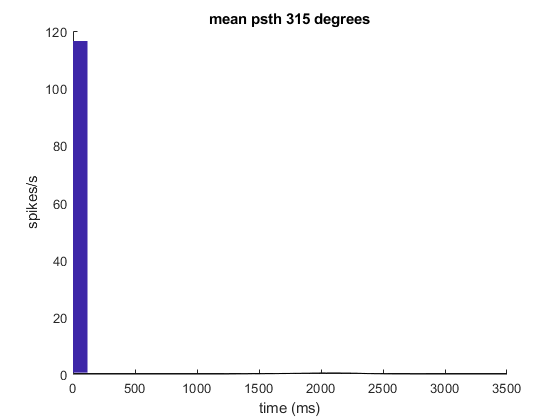

n = numBins;
p90 = psths_allDirections(3, :);
e90 = err_allDirections(3, :);
p270 = psths_allDirections(7, :);
e270 = err_allDirections(7, :);
p0 = psths_allDirections(1, :);
e0 = err_allDirections(1, :);

filt = p270;
noise = e270;
%filt = p270/max(p270);
%filt = p0/max(p0);

binWidth = totalTime/numBins; %ms, time between each bin in the filter
vid = VideoWriter('waveProp270Noise.avi');
vid.FrameRate = 30;
open(vid);
for i = 1:numBins*2
    filterIndices = [-1:-1:-numBins] + i;
    inPlay = filterIndices(filterIndices>0 & filterIndices<numBins);
    values = filt(inPlay);
    noises = noise(inPlay);
    arrayResponse = zeros(1, n);
    arrayResponse(1, fliplr(inPlay)) = values;
    retinaMatrix = repmat(arrayResponse, [n, 1]);
    
    noiseResponse = zeros(1, n);
    noiseResponse(1, fliplr(inPlay)) = noises;
    noiseMatrix = zeros(n);
    for j = 1:n
        noiseMatrix(:, j) = randn(1, n) .* 0.3.*noiseResponse(j)./arrayResponse(j);
    end
    
    signalAndNoise = noiseMatrix + retinaMatrix;
    
    imagesc(signalAndNoise);
    caxis([0 1])
    frame = getframe;
    writeVideo(vid,frame);
end

close(vid);



## Plot signal to noise for each direction

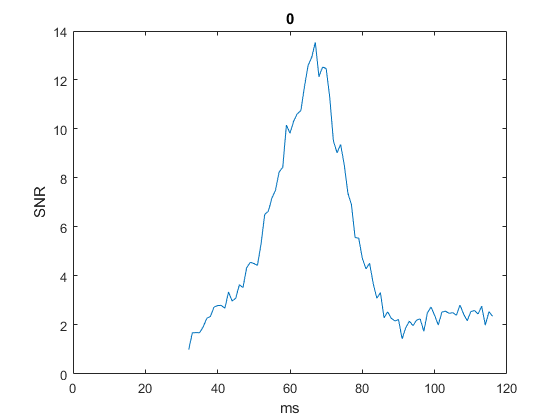

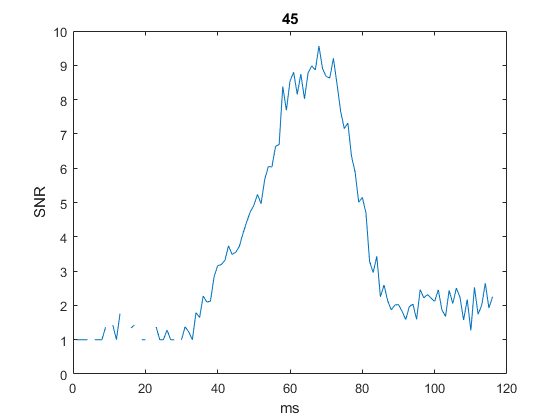

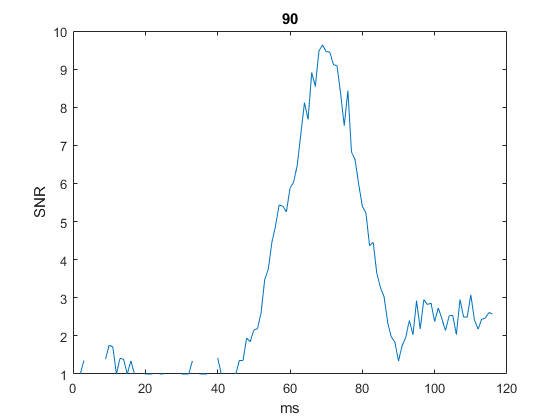

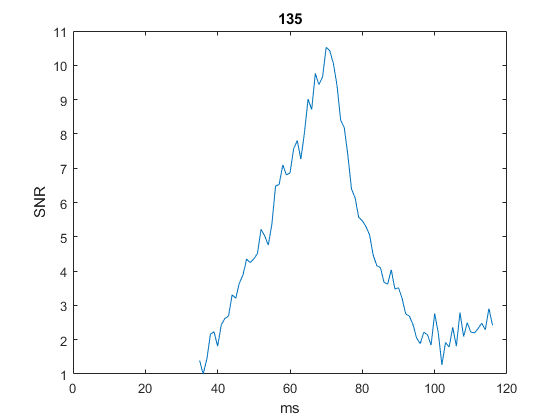

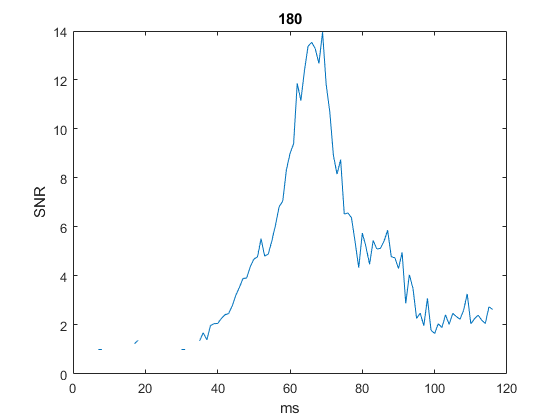

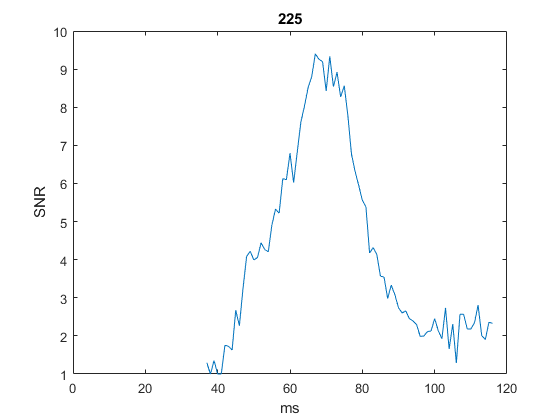

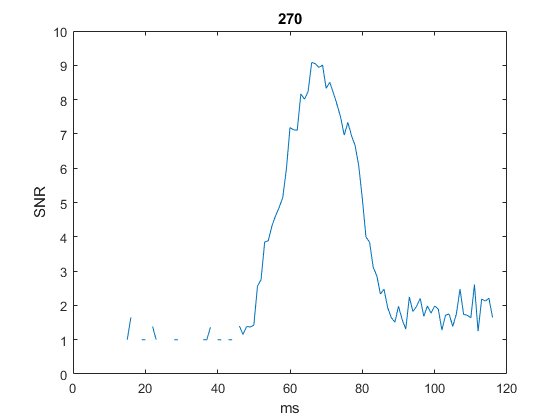

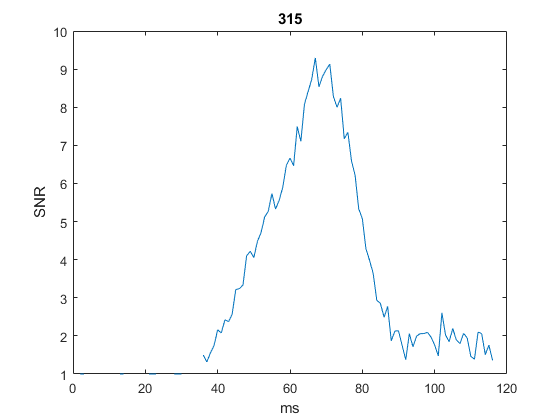

for i = 1:8
    figure
    plot(psths_allDirections(i, :)./err_allDirections(i, :))
    hold on
    title(num2str((i-1)*45))
    xlabel('ms')
    ylabel('SNR')
end

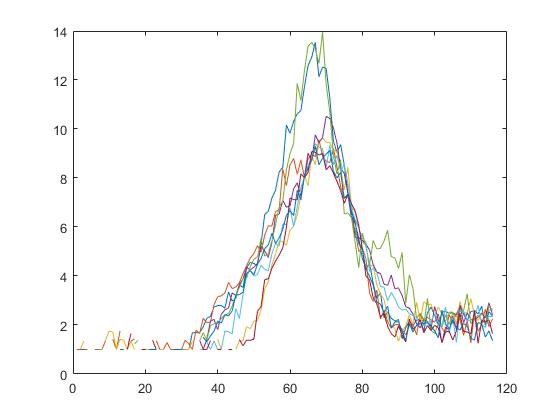

figure
for i = 1:8
    plot(psths_allDirections(i, :)./err_allDirections(i, :))
    hold on
end